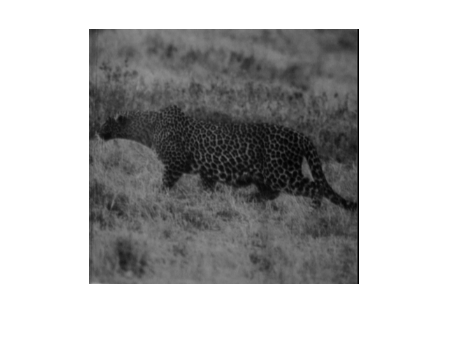

Prior probability of cheetah:
    0.1919

Prior probability of grass:
    0.8081



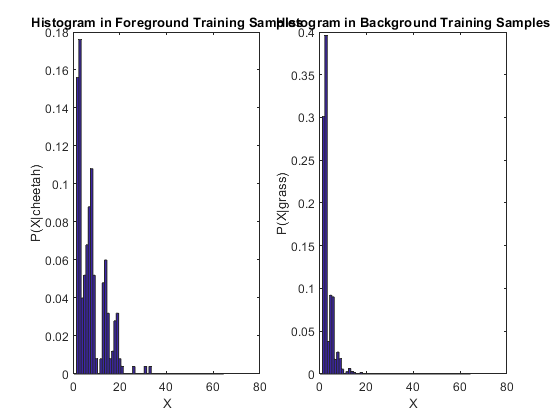

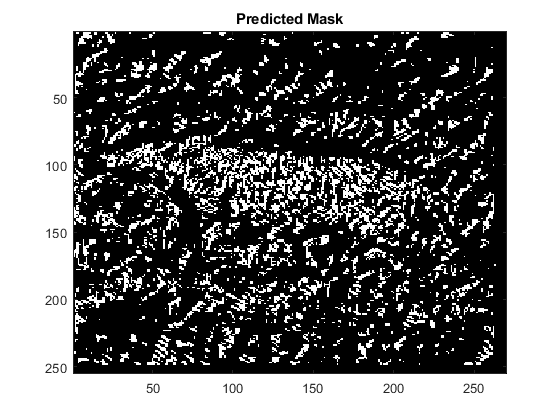

Error rate(%):
   23.8126



close all; clear; clc;

## **Basic Description**

The Input image is a 255*270 pixels gray-scaled image. As this image shown, the texture between cheetah, which is our object and foreground, and grass is quite different. The background(grass) has more uniform intensities than the foreground, which can make a seperation in frequenct domain. Our purposed method is statistical learning with bayesian decision theory using features in frequency domauin. Firstly, to take each component in the rule, its necessary to understand how the data distributed by prior probability.

%% Data import

img = imread('cheetah.bmp');
imshow(img);
zz_order = dlmread('Zig-Zag Pattern.txt');
load('TrainingSamplesDCT_8.mat');
N = 8;

## Prior Probability

The prior probabilities can be simply acquired by calculating the ratio of two classes in training samples. The prior probability of foreground is 0.1919, and 0.8081 for background. This question simply takes this "cheetah segmentation" as binary classification, which composed of two classes. And we can observe that the ratio of background is much higher than foreground.

%% Problem 1: Priors
% Priors of background and foreground are directly acquired by calculate
% the ratio of traing samples in each class

c_size = size(TrainsampleDCT_FG,1);
g_size = size(TrainsampleDCT_BG,1);

P_c = c_size / (c_size + g_size);
P_g = g_size / (c_size + g_size);

disp('Prior probability of cheetah:')
disp(P_c)
disp('Prior probability of grass:')
disp(P_g)

% Feature vector: location of the coefficient of 2nd largest magnitude,
BG_X = feature_vector_DCT(TrainsampleDCT_BG);
FG_X = feature_vector_DCT(TrainsampleDCT_FG);